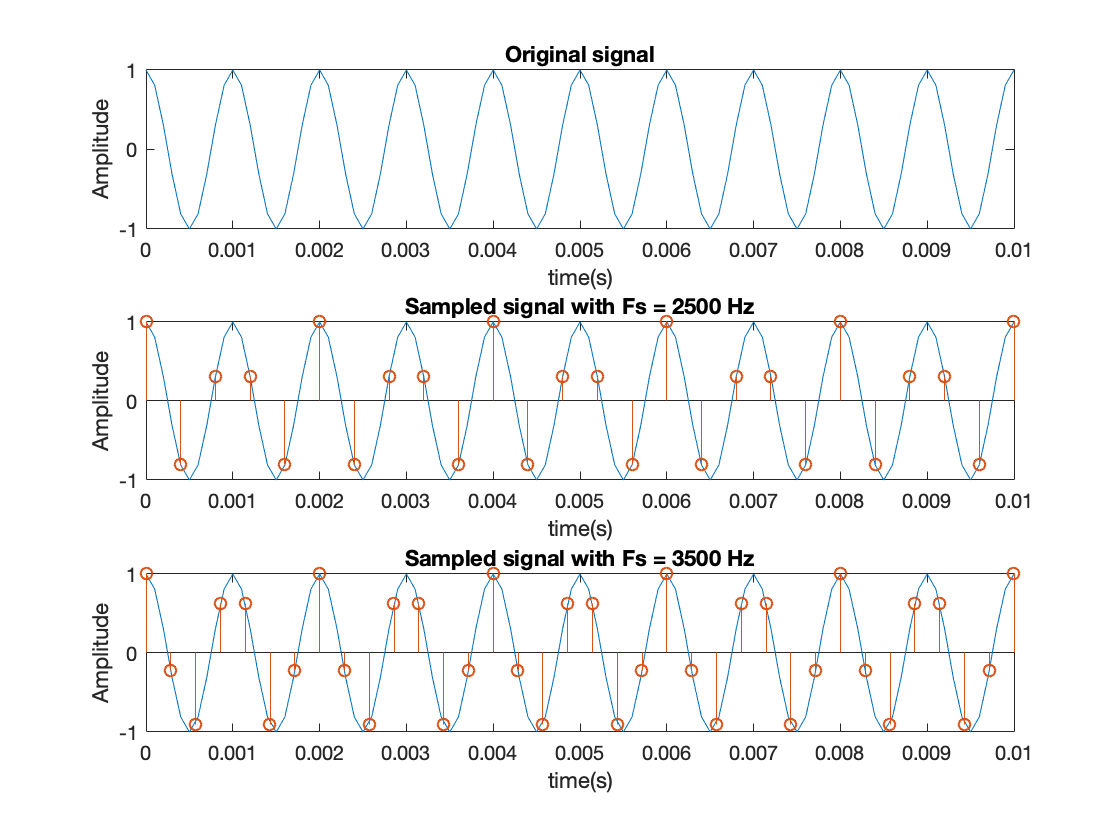

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : Sampling
%----------------------------------------------------------------------
close all;
clc;

%x_a(t) = cos(2000*pi*t) - it is approximated as discrete 
%by chossing decimated time points

T = 1000;%signal time period
Fs = 10000; %sampling frequency
Ts = 1/Fs; %sampling period
ncycle = 10; %no of cycles to consider
t = 0:Ts:ncycle/T;
L = length(t);

%given signal
x_a = cos(2000.*pi.*t);

subplot(3,1,1);
plot(t,x_a);
xlabel('time(s)');
ylabel('Amplitude');
title('Original signal');
hold on
%computing fourier transform 
%approximating signal as bandlimited from w = -10000 to 10000
X = zeros(1, L);


%sampling the signal
Fs1 = 2500;
Fs2 = 3500;

t1 = 0:1/Fs1:ncycle/T;
t2 = 0:1/Fs2:ncycle/T;

x1 = cos(2000.*pi.*t1); %sequence 1
x2 = cos(2000.*pi.*t2); %sequence 2

%plot sampled signal with Fs = 2500 Hz
subplot(3,1,2);
plot(t,x_a);
hold on
stem(t1,x1);
xlabel('time(s)');
ylabel('Amplitude');
title('Sampled signal with Fs = 2500 Hz');

%plot sampled signal with Fs = 3500 Hz
subplot(3,1,3);
plot(t,x_a);
hold on
stem(t2,x2);
xlabel('time(s)');
ylabel('Amplitude');
title('Sampled signal with Fs = 3500 Hz');